%% LINEAR REGRESSION AND LSTM ISO-NE Smart City Energy Forecasting (Kaggle Dataset)
% Author: Marie Elster, Lauren Popinchalk, Alexa Butterfield
% Requirements: Deep Learning Toolbox, Statistics & Machine Learning Toolbox

clc; clear; close all;

%% 1. Load dataset
data = readtable('smart_city_energy_dataset.csv');

head(data)

         Timestamp         HourOfDay    DayOfWeek    IsWeekend    IsHoliday    Season    WeekOfYear    Month    HistoricalElectricityLoad_kW_    PeakLoadIndicator    LoadSectorType     TransformerLoadLevel    VoltageLevel_V_    CurrentLevel_A_    PowerFactor    SubstationID_RegionID    DemandResponseSignal_Binary_    GridFrequency_Hz_    SolarPVOutput_kW_    WindPowerOutput_kW_    SolarPanelTemperature__C_    WindSpeed_m_s_    WindDirection_degrees_    InverterEfficiency___    BatteryStateOfCharge_SOC____    BatteryDischargeRate_kW_h_    Renewa

% ADDING LAG FEATURES
% Ensure data is time-ordered
data = sortrows(data, 'Timestamp');

% --- Add lag features (1 hour, 24 hours, 168 hours) ---
data.Lag1   = [NaN; data.ElectricityLoad(1:end-1)];
data.Lag24  = [NaN(24,1); data.ElectricityLoad(1:end-24)];
data.Lag168 = [NaN(168,1); data.ElectricityLoad(1:end-168)];

% Remove rows with missing lag data
data = rmmissing(data);

%autocorr(data.ElectricityLoad);
head(data)

         Timestamp         HourOfDay    DayOfWeek    IsWeekend    IsHoliday    Season    WeekOfYear    Month    HistoricalElectricityLoad_kW_    PeakLoadIndicator    LoadSectorType     TransformerLoadLevel    VoltageLevel_V_    CurrentLevel_A_    PowerFactor    SubstationID_RegionID    DemandResponseSignal_Binary_    GridFrequency_Hz_    SolarPVOutput_kW_    WindPowerOutput_kW_    SolarPanelTemperature__C_    WindSpeed_m_s_    WindDirection_degrees_    InverterEfficiency___    BatteryStateOfCharge_SOC____    BatteryDischargeRate_kW_h_    Renewa

%{
%INSPECTING FREQENCY DOMAIN
Fs = 1; % 1 sample/hour
load_signal = detrend(data.ElectricityLoad);
L = length(load_signal);
Y = fft(load_signal);
f = Fs*(0:(L/2))/L;
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
plot(f, P1);
xlabel('Frequency (cycles/hour)');
ylabel('Magnitude');
title('Power Spectrum of Electricity Load');
%}

%%FEAUTURE SELECTION
%% 2. Select relevant features
features1 = {'HourOfDay', 'DayOfWeek', 'IsWeekend', 'IsHoliday', ...
            'Season', 'Month', ...
            'VoltageLevel_V_', 'CurrentLevel_A_', 'PowerFactor', 'TransformerLoadLevel', ...
            'Temperature__C_', 'Humidity___', 'SolarIrradiance_W_m__', 'CloudCover___', 'WindSpeed_m_s_', ...
            'EVChargingStationLoad_kW_', 'PublicTransitOperationalLoad_kW_', ...
            'HumanMobilityScore', 'RegionUrbanDensityIndex'};

features2 = {'HourOfDay', 'DayOfWeek', 'IsWeekend', 'IsHoliday', ...
            'Season', 'Month', 'Temperature__C_', 'Humidity___', 'SolarIrradiance_W_m__', 'CloudCover___', 'WindSpeed_m_s_'};

featuresLag = {'HourOfDay', 'DayOfWeek', 'IsWeekend', 'IsHoliday', ...
            'Season', 'Month', 'Temperature__C_', 'Humidity___', ...
            'SolarIrradiance_W_m__', 'CloudCover___', 'WindSpeed_m_s_', ...
            'Lag1', 'Lag24', 'Lag168', 'HistoricalElectricityLoad_kW_'};

%ADDING FOURIER TERMS
data.SinDaily = sin(2*pi*data.HourOfDay/24);
data.CosDaily = cos(2*pi*data.HourOfDay/24);
featuresFour = [features2, {'SinDaily', 'CosDaily'}];

target = 'ElectricityLoad';
features = featuresLag;

%% 3. Extract X and y
X = data{:, features};
y = data{:, target};

%% 4. Handle missing data
X = fillmissing(X, 'linear');
y = fillmissing(y, 'linear');

X = normalize(X); % normalize data

%% 5. Split into training (80%) and testing (20%)
n = size(X,1);
idx = randperm(n);
train_size = round(0.8 * n);

X_train = X(idx(1:train_size), :);
y_train = y(idx(1:train_size), :);
X_test  = X(idx(train_size+1:end), :);
y_test  = y(idx(train_size+1:end), :);

%% 6. Train linear regression model
mdl = fitlm(X_train, y_train, 'Intercept', true);

%% 7. Display summary
disp(mdl);


Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15

Estimated Coefficients:
                   Estimate        SE        tStat       pValue 
                   _________    ________    ________    ________

    (Intercept)       451.12    0.082861      5444.3           0
    x1             -0.032946    0.082788    -0.39796     0.69066
    x2             -0.063128     0.13506    -0.46739     0.64022
    x3               0.17236     0.13526      1.2743     0.20258
    x4              -0.13526    0.082964     -1.6303     0.10304
    x5             -0.048444    0.082969    -0.58388     0.55931
    x6              0.017586    0.082855     0.21225     0.83191
    x7   

%% 8. Predict on test data
y_pred = predict(mdl, X_test);

% show some predictions
numSamplesToShow = 10;
fprintf('\nSample Predictions vs Actual:\n');


Sample Predictions vs Actual:


fprintf('Idx\tActual(kW)\tPredicted(kW)\tError(kW)\n');

Idx	Actual(kW)	Predicted(kW)	Error(kW)


for i = 1:numSamplesToShow
    fprintf('%d\t%.2f\t\t%.2f\t\t%.2f\n', i, y_test(i), y_pred(i), y_pred(i)-y_test(i));
end

1	697.40		708.49		11.09
2	834.68		828.26		-6.42
3	276.43		292.93		16.51
4	829.88		815.73		-14.15
5	529.22		518.79		-10.43
6	278.75		249.56		-29.18
7	552.27		527.12		-25.15
8	811.20		790.35		-20.84
9	252.50		238.61		-13.89
10	493.75		529.24		35.49


%% 9. Evaluate performance
rmse = sqrt(mean((y_pred - y_test).^2));
r2 = 1 - sum((y_test - y_pred).^2) / sum((y_test - mean(y_test)).^2);

fprintf('\nModel Performance:\n RMSE: %.3f\n R^2: %.3f\n',rmse, r2);


Model Performance:
 RMSE: 20.013
 R^2: 0.994


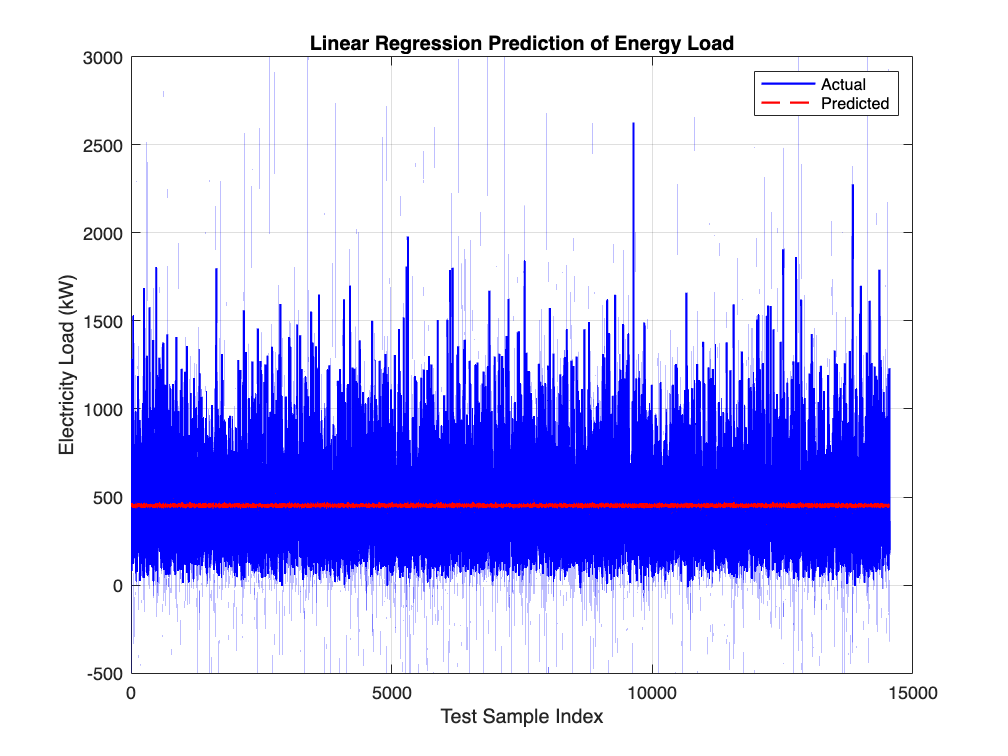

%% 10. Plot actual vs predicted
figure;
plot(y_test, 'b', 'LineWidth', 1.2); hold on;
plot(y_pred, 'r--', 'LineWidth', 1.2);
legend('Actual', 'Predicted');
xlabel('Test Sample Index');
ylabel('Electricity Load (kW)');
title('Linear Regression Prediction of Energy Load');
grid on;

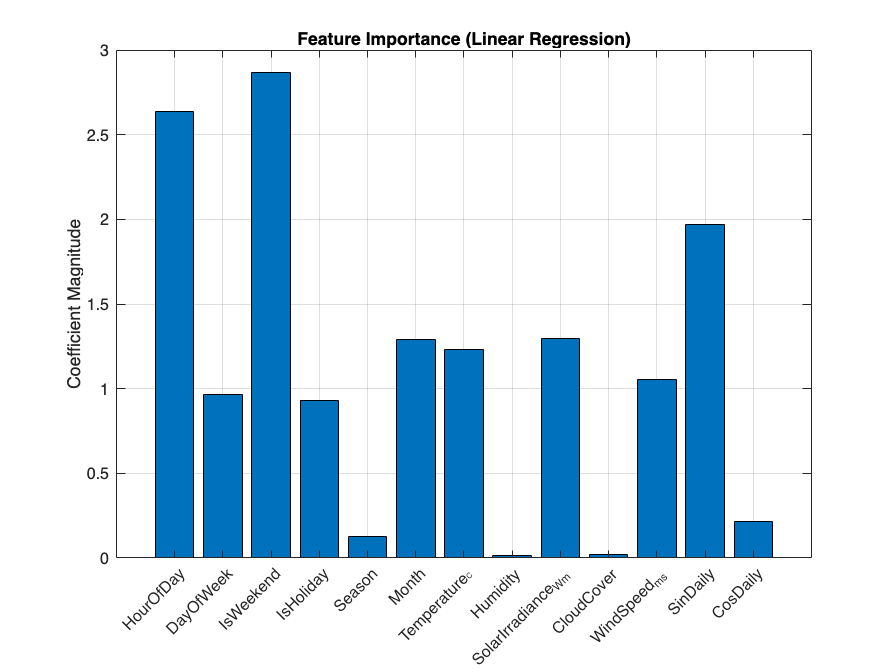


%% 11. Feature importance (from coefficients)
coeffs = mdl.Coefficients.Estimate(2:end);
figure;
bar(abs(coeffs));
xticklabels(features);
xtickangle(45);
ylabel('Coefficient Magnitude');
title('Feature Importance (Linear Regression)');
grid on;

%% LSTM
%LSTMs need sequences, not tabular samples.
%We’ll predict load from the previous seqLen hours.
selectedFeatures = featuresLag;

Xdata = data{:, selectedFeatures};
Ydata = data.ElectricityLoad;

seqLen = 24;
loadSignal = data.ElectricityLoad;

% Normalize
mu = mean(loadSignal, 'omitnan');
sigma = std(loadSignal, 'omitnan');
loadNorm = (loadSignal - mu) / sigma;

% Build sequences correctly
X = {};
Y = [];
Xnorm = normalize(Xdata);

for i = 1:(height(Xnorm) - seqLen)
    X{end+1} = Xnorm(i:i+seqLen-1, :)';   % [numFeatures × seqLen]
    Y(end+1) = Ydata(i+seqLen);
end

% Double-check sizes match before splitting
disp([length(X), length(Y)])  % should be identical

       72768       72768




% Split train/test
numTrain = floor(0.8 * numel(X));

XTrain = X(1:numTrain);
YTrain = Y(1:numTrain);
XTest  = X(numTrain+1:end);
YTest  = Y(numTrain+1:end);

disp([length(XTrain), length(YTrain)])   % check again

       58214       58214



YTrain = YTrain(:);
class(XTrain)

ans = 'cell'

class(YTrain)

ans = 'double'

size(YTrain)

ans =        58214           1


%use subset for faster training
subset = 1:5000;   % use first 5000 samples
XTrain = XTrain(subset);
YTrain = YTrain(subset);

%Train LSTM
inputSize = numel(selectedFeatures);
numHiddenUnits = 100;
numResponses = 1;

layers = [
    sequenceInputLayer(inputSize)
    lstmLayer(50, 'OutputMode', 'last')
    fullyConnectedLayer(1)
    regressionLayer
];


%options = trainingOptions('adam', ...
%    'MaxEpochs', 100, ...
%    'MiniBatchSize', 64, ...
%    'GradientThreshold', 1, ...
%    'InitialLearnRate', 0.005, ...
%    'Plots', 'training-progress', ...
%    'Verbose', 0);

options = trainingOptions('adam', ...
    'MaxEpochs', 30, ...
    'MiniBatchSize', 256, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'ExecutionEnvironment', 'auto', ...
    'Plots', 'none', ...
    'Verbose', 0);

net = trainNetwork(XTrain, YTrain, layers, options);
fprintf('done training');

done training


%%Evaluate Performance

YPred = predict(net, XTest);

% Denormalize
YTestDenorm = YTest * sigma + mu;
YPredDenorm = YPred * sigma + mu;

% Evaluate
rmseLSTM = sqrt(mean((YPredDenorm - YTestDenorm).^2));
R2LSTM = 1 - sum((YPredDenorm - YTestDenorm).^2) / sum((YTestDenorm - mean(YTestDenorm)).^2);

fprintf('LSTM RMSE: %.3f\n', rmseLSTM);

LSTM RMSE: 77115.492
LSTM RMSE: 70066.500
LSTM RMSE: 56046.508
LSTM RMSE: 163887.875
LSTM RMSE: 94037.148
LSTM RMSE: 45641.031
LSTM RMSE: 37438.070
LSTM RMSE: 44032.590
LSTM RMSE: 167443.797
LSTM RMSE: 50419.898
LSTM RMSE: 72260.805
LSTM RMSE: 136669.812
LSTM RMSE: 34914.355
LSTM RMSE: 45156.199
LSTM RMSE: 60890.086
LSTM RMSE: 63088.137
LSTM RMSE: 20517.445
LSTM RMSE: 116990.195
LSTM RMSE: 94007.844
LSTM RMSE: 82426.695
LSTM RMSE: 42868.523
LSTM RMSE: 33424.723
LSTM RMSE: 168669.516
LSTM RMSE: 82175.570
LSTM RMSE: 74478.305
LSTM RMSE: 67098.422
LSTM RMSE: 176003.484
LSTM RMSE: 74245.758
LSTM RMSE: 53978.375
LSTM RMSE: 31907.902
LSTM RMSE: 25522.348
LSTM RMSE: 92190.461
LSTM RMSE: 295645.375
LSTM RMSE: 75019.422
LSTM RMSE: 23141.004
LSTM RMSE: 65887.906
LSTM RMSE: 175044.203
LSTM RMSE: 253435.547
LSTM RMSE: 39229.285
LSTM RMSE: 203779.812
LSTM RMSE: 58806.891
LSTM RMSE: 56034.188
LSTM RMSE: 237585.609
LSTM RMSE: 36382.086
LSTM RMSE: 21515.357
LSTM RMSE: 159056.219
LSTM RMSE: 153545.828


fprintf('LSTM R^2: %.3f\n', R2LSTM);

LSTM R^2: -0.265
LSTM R^2: -0.044
LSTM R^2: 0.332
LSTM R^2: -4.712
LSTM R^2: -0.881
LSTM R^2: 0.557
LSTM R^2: 0.702
LSTM R^2: 0.588
LSTM R^2: -4.963
LSTM R^2: 0.459
LSTM R^2: -0.111
LSTM R^2: -2.973
LSTM R^2: 0.741
LSTM R^2: 0.566
LSTM R^2: 0.211
LSTM R^2: 0.154
LSTM R^2: 0.910
LSTM R^2: -1.911
LSTM R^2: -0.880
LSTM R^2: -0.445
LSTM R^2: 0.609
LSTM R^2: 0.762
LSTM R^2: -5.051
LSTM R^2: -0.436
LSTM R^2: -0.180
LSTM R^2: 0.042
LSTM R^2: -5.588
LSTM R^2: -0.172
LSTM R^2: 0.380
LSTM R^2: 0.783
LSTM R^2: 0.861
LSTM R^2: -0.808
LSTM R^2: -17.589
LSTM R^2: -0.197
LSTM R^2: 0.886
LSTM R^2: 0.077
LSTM R^2: -5.517
LSTM R^2: -12.660
LSTM R^2: 0.673
LSTM R^2: -7.832
LSTM R^2: 0.265
LSTM R^2: 0.332
LSTM R^2: -11.005
LSTM R^2: 0.718
LSTM R^2: 0.902
LSTM R^2: -4.380
LSTM R^2: -4.014
LSTM R^2: -1.035
LSTM R^2: 0.660
LSTM R^2: -5.684
LSTM R^2: -2.442
LSTM R^2: -1.828
LSTM R^2: -1.266
LSTM R^2: -6.359
LSTM R^2: -4.283
LSTM R^2: -3.957
LSTM R^2: -1.533
LSTM R^2: -0.983
LSTM R^2: -0.861
LSTM R^2: -0.142
L


% Plot comparison
figure;
plot(YTestDenorm, 'b'); hold on;
plot(YPredDenorm, 'r--');
legend('Actual Load', 'Predicted Load');
xlabel('Time Step'); ylabel('Electricity Load (kW)');
title('LSTM Prediction vs Actual');
